Ordningnr1 = 16.0435


Ordningnr2 = 16.1309


Felet första halvering (del 1) = 0.0000000000705


Felet andra halvering (del 1) = 0.0000000000044


Felet första halvering (del 2) = 0.0000000000727


Felet andra halvering (del 2) = 0.0000000000045


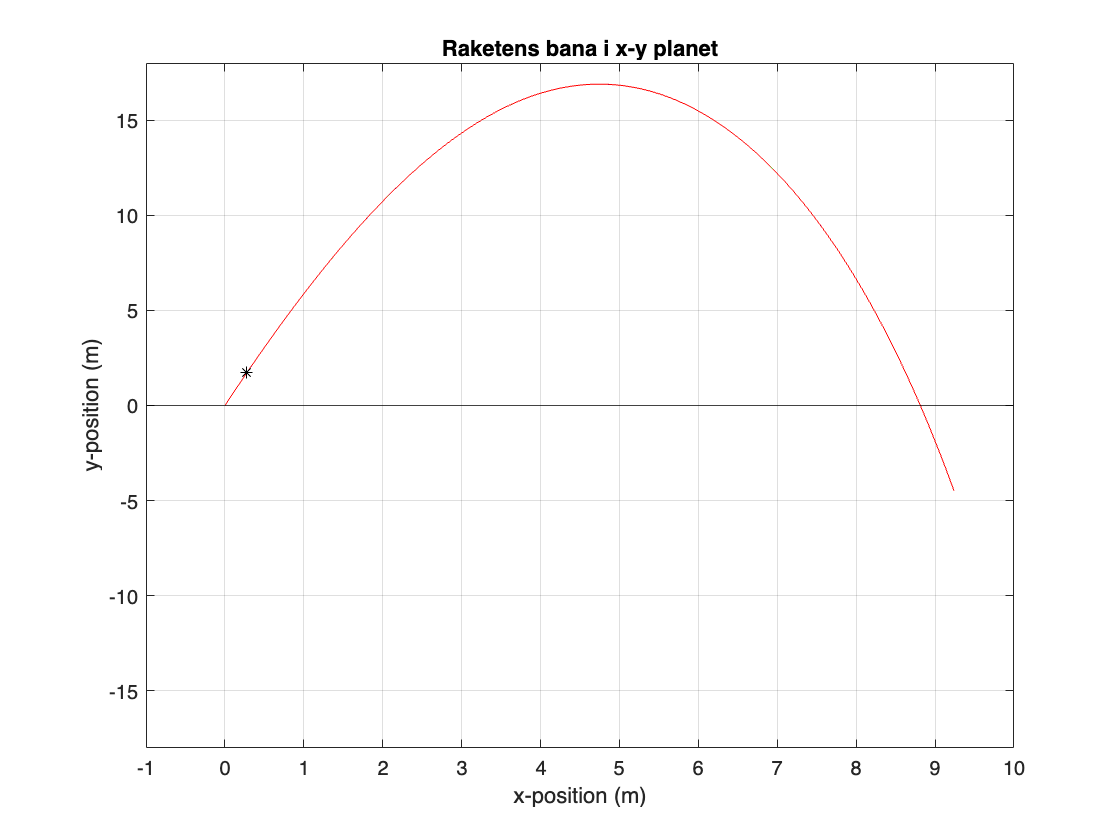

clear all, close all, clf

%bordsraket
v_yx = 21; %hastighet initialt
teta = deg2rad(81); %vinkel initialt
h=0.01;
F=1; %kraften
t1=0;
t2=0.08;
tend=4;
%funktion
[z1,z2,z3,t_vals1,t_vals2,t_vals3,Error] = Rocketman(t1,t2,tend,h,F,v_yx,1);
graderVektor=getdegvec(t_vals1,h,z1);
ord1=Error(2,4);
ord2=Error(3,4);
delta11=Error(2,2);
delta12=Error(3,2);
delta21=Error(2,3);
delta22=Error(3,3);
ordningen ='≈16';
fprintf('Ordningnr1=%.4f\n',ord1);
fprintf('Ordningnr2=%.4f\n',ord2);
fprintf('felet första halvering i första delen=%.13f\n',delta11);%första delen är med F=1
fprintf('felet andra halvering i första delen=%.13f\n',delta12);
fprintf('felet första halvering i andra delen=%.13f\n',delta21);%andra delen är med F=0
fprintf('felet andra halvering i andra delen=%.13f\n',delta22);
%phi1=180*atan(z1(4,9)/z1(3,9))/pi;
%phi2=180*atan(z2(4,17)/z1(3,17))/pi;
%fprintf('_phi1=%.4f\n',phi1);
%fprintf('_phi2=%.4f\n',phi2);
% Plotta lösningen
figure;
plot(z1(1,:), z1(2,:), 'b'); 
hold on
plot(z2(1,:), z2(2,:), 'g'); 
plot(z3(1,:), z3(2,:), 'r');
plot(z3(1,34), z3(2,34), '*-k');

%plot(z4(1,:), z4(2,:), 'y');
%plot(z5(1,:), z5(2,:), 'k');
xlim([-1,10])
ylim([-18,18]);
yline(0,'-k')
xlabel('x-position (m)'); 
ylabel('y-position (m)');
title('Raketens bana i x-y planet');
%legend(['h = ' num2str(h)], ['h2 = ' num2str(h2)], ['h3 = ' num2str(h3)],['h4 = ' num2str(h4)]);
grid on;

%funktion som levererar lösningar halverad steglängd och nr är vilken
%lösning vi tittar på felet
function [z1,z2,z3,t_vals1,t_vals2,t_vals3,Error] = Rocketman(t1,t2,tend,h,F,v_yx,nr1)
    %Parametrar
    teta = 81*(pi/180);
    x0=0;
    y0=0;
    halvering = [1,2,4];
    %zpart1[] = [];
    %zpart2 = [];
    steg = zeros(3,1);
    [xv,yv] = velocity(v_yx,teta);
    for i=1:3
        hi=h/halvering(i);
        steg(i) = hi;
        [zd11, t_vals11] = RungeKutta(t1,t2,0,hi,F,x0,y0,xv,yv);
        zpart1{i} = zd11;
        tpart1{i} = t_vals11;
    end
    [E1,pp1] = error_calc(zpart1,nr1);
    initial = zpart1{3};% plockar ut hastigheten med minst fel
    for j=1:3
        hj=h/halvering(j);
        
        [zd21, t_vals21] = RungeKutta(t2,tend,0,hj,0,initial(1,end),initial(2,end),initial(3,end),initial(4,end));
        zpart2{j} = zd21;
        tpart2{j} = t_vals21;
    end
    [E2,pp2] = error_calc(zpart2,nr1);
    ordning = zeros(3,1);
    ordning(2) = pp1;
    ordning(3) = pp2;
    t11 = tpart1{1}; t21 = tpart2{1};
    t12 = tpart1{2}; t22 = tpart2{2};
    t13 = tpart1{3}; t23 = tpart2{3};
    z11 = zpart1{1}; z21 = zpart2{1};
    z12 = zpart1{2}; z22 = zpart2{2};
    z13 = zpart1{3}; z23 = zpart2{3};
    z1 = [z11, z21(:,2:end)];
    z2 = [z12, z22(:,2:end)];
    z3 = [z13, z23(:,2:end)];
    t_vals1 = [t11,t21(2:end)];
    t_vals2 = [t12,t22(2:end)];
    t_vals3 = [t13,t23(2:end)];
    Error = [steg,E1,E2,ordning];
end

function [E,pp] = error_calc(zz,nr)
    %nr är vilken del av matrisen alltså läget eller farten
    E = zeros(3,1);
    z11 = zz{1};
    z22 = zz{2};
    z33 = zz{3};
    pp= (z11(nr,end)-z22(nr,end))/(z22(nr,end)-z33(nr,end));
    E(2) = z22(nr,end)-z11(nr,end);
    E(3) = z33(nr,end)-z22(nr,end);
end
%RUnge kutta som löser diffekva
function [z_val,t_vals] = RungeKutta(a,b,N,h,v,x0,y0,xdot0,ydot0)
    
    t_vals = a:h:b;
    N = length(t_vals);
    z = zeros(4,N);
    
    z(:,1) = [x0; y0; xdot0; ydot0];%z ären matris med x,y, xprick och yprick
    %Runge-kutta
    for i = 1:N-1
        t = t_vals(i);
        z_i = z(:,i);
        k1 = funcsolve(t,z_i,v);
        k2 = funcsolve(t + h/2 ,z_i + (h/2)*k1,v);
        k3 = funcsolve(t + h/2 ,z_i + (h/2)*k2,v);
        k4 = funcsolve(t + h ,z_i + h*k3,v);
        z(:,i+1) = z_i + (k1 + 2*k2 + 2*k3 + k4)*(h/6);
        
    end

    z_val = z;

end
%funktion för hastighetskomponenter
function [xvl,yvl] = velocity(vxy,teta)
    
    xvl = vxy*cos(teta);
    yvl = vxy*sin(teta);
end
%funktion för massan
function mass = M(m0,t)
    if t<= 0.08
        mass = m0-0.08*t;
    else
        mass = m0-0.08*0.08;%massa kvar efter brinntid
    end
end
%funktion för dragkraft

function force = F_lyft(t,s)
    if t<= 0.08
        force = s;
    else
        force = 0;
    end
end
%funktion beräkning av grader
function phi = anglecal(t,vvx,vvy)
    if t<=0
        phi = deg2rad(81);
    else
        phi = atan(vvy/vvx);
    end
end
%kolla så att gradfunktionen funkar
function degrevector = getdegvec(tvalue,h,hasv)
    %tvalue=t11:h:t22;
    deg = [];
    for i=1:length(tvalue)
        deg(i) = 180*anglecal(tvalue(i),hasv(3,i),hasv(4,i))/pi;

        
    end
    degrevector =deg;
end
%funktionen för diffekvationerna
function dzdt = funcsolve(t,z,v)
    %parametrar
    x = z(1);
    y = z(2);
    x_dot = z(3);
    y_dot = z(4);
    g=9.82;
    m0 = 0.05;
    k_x=0.001;
    k_y=k_x;
    k=0.08;
    
    %system av diffekvationer
    dzdt = zeros(4,1);
    dzdt(1) = x_dot;
    dzdt(2) = y_dot;
    dzdt(3) = (F_lyft(t,v)*cos(anglecal(t,x_dot,y_dot)) -k_x*x_dot*sqrt(x_dot^2+y_dot^2))/M(m0,t);
    dzdt(4) = (F_lyft(t,v)*sin(anglecal(t,x_dot,y_dot)) -k_y*y_dot*sqrt(x_dot^2+y_dot^2))/M(m0,t) -g; 

    %dzdt = dzdt';



end
